Frist exp 1-1:

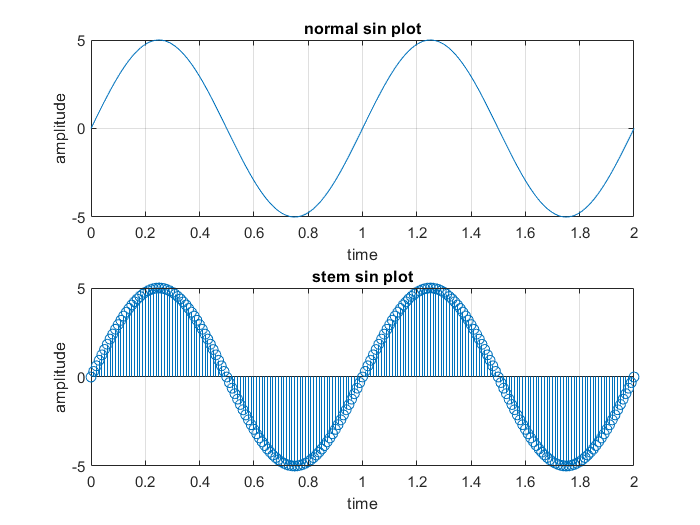

clc;
clear;
close all;
%% part 1 
t= 0 : 0.01 : 2 ;
y= 5 * sin (2 * pi * t);
figure (1);
subplot(2 ,1, 1);
plot (t , y);
grid on;
xlabel("time");
ylabel("amplitude");
title("normal sin plot");
subplot(2 ,1 ,2);
stem(t , y);
xlabel("time");
ylabel("amplitude");
title("stem sin plot");
grid on;

As you can see, the axes are named and the parameters are certain values.

part 1-2

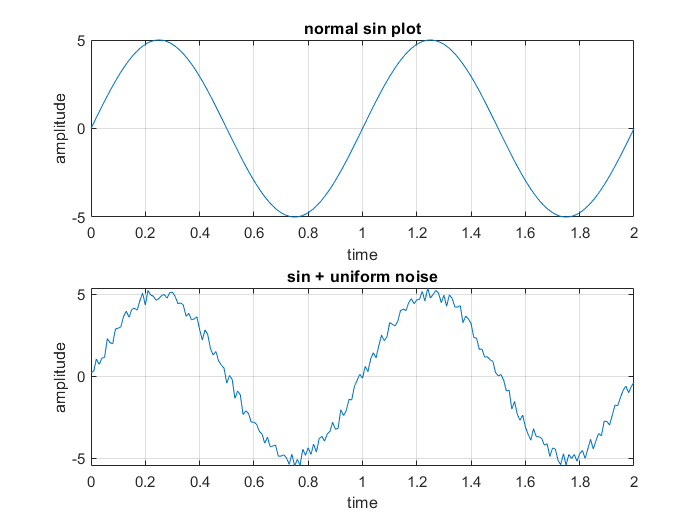

%%part 2
n = rand (1 , numel (y))- 0.5;
y_n = y + n ;%Adding a uniform noise to the sin signal
figure (2);
subplot (2 , 1, 1);
plot (t , y);
grid on;
xlabel("time");
ylabel("amplitude");
title("normal sin plot");

subplot (2 , 1, 2);
plot (t , y_n);
title("sin + uniform noise");
xlabel("time");
ylabel("amplitude");
grid on;

part 1-3:

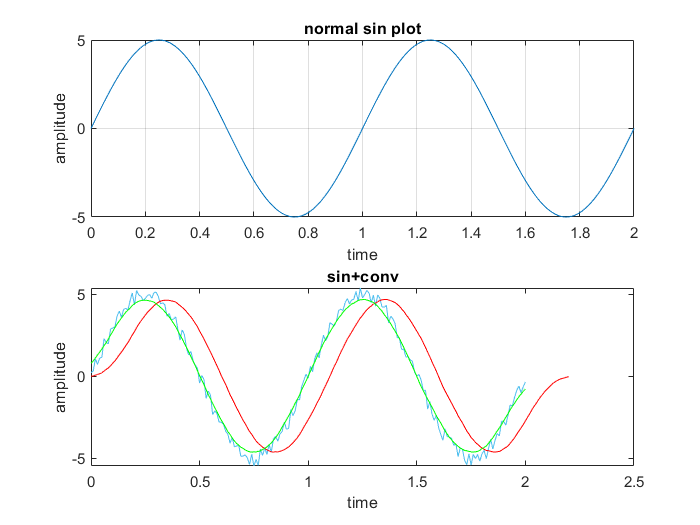

%% part 3
N=21; %when M2 =20 number of points is 21
x= ones (1,N)/N ;
y_c = conv (y_n , x);
y_c2 = conv (y_n , x,"same");
t2 = 0 : 0.01 : (0.01 * (numel (y_c)-1));
t2s = 0 : 0.01 : (0.01 * (numel (y_c2)-1));
figure (2);
%subplot (2 , 1, 2);
plot (t , y_n);
title("sin+noise");
xlabel("time");
ylabel("amplitude");
hold on;
%subplot (2 , 1, 2);
plot (t2 , y_c , 'r');
title("sin+conv");
xlabel("time");
ylabel("amplitude");
hold on;
plot (t2s , y_c2 , 'g');
hold on ;

As you can see, there is a time delay, each term of the filter creates a delay, as a result, when the new signal wants to pass through the filter, it must calculate the average of the (M1+M2+1) term together. As a result, when M1=ء2=10, we will have a delay.

part 1-4

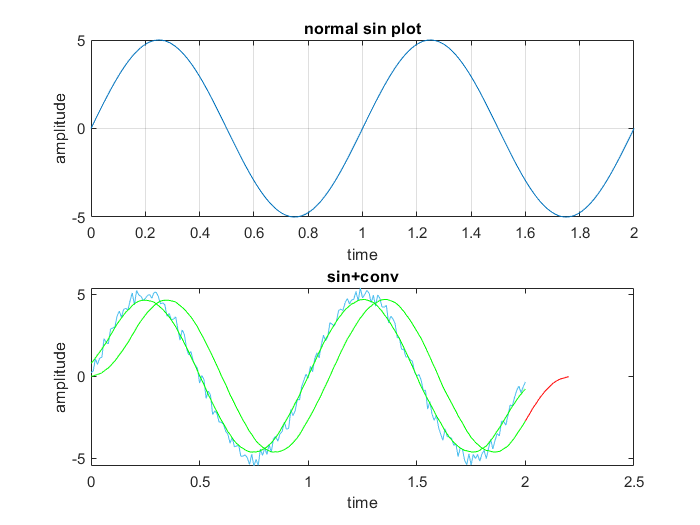

b = ones (1 , N ) / N ;
y_f = filter (b , 1 , y_n);
figure (2);
%subplot(2 , 1 , 2);
plot (t2 , y_c , 'r');
hold on ;
plot(t ,y_f , 'g' );

As you can see, it is completely similar to the previous part.

part 1-5

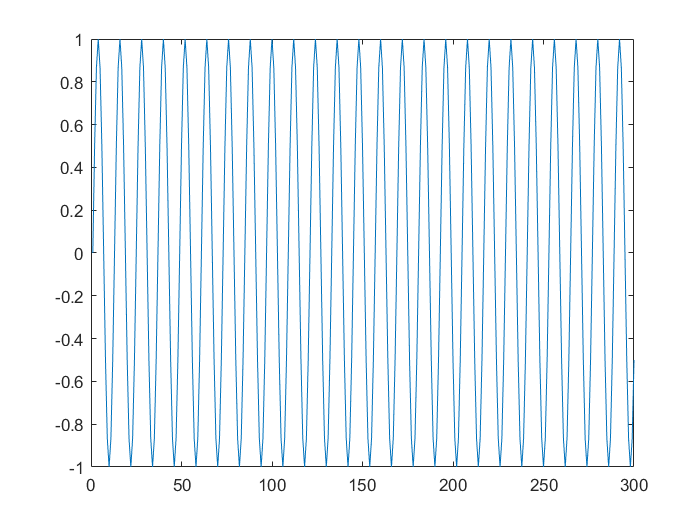

n = 1:300 ;
y_ff = singen(pi/6 , 300);
figure (3);
plot(n , y_ff);

function  y1 = singen (w , n)
 b = [0 , sin(w)];
 a = [1 , -2* cos(w), 1] ; 
 x_1 = zeros (1 ,n);
 x_1 (1)=1;
 y1 = filter (b ,a , x_1);
end